## Mars Communication Simulation

### Eddy Zhong

#### Goal: To design and verify a communication system that transmits in the presence of cosmic background noise MNIST images from Mars to Earth as intelligible images. 

## Design constraints.

Electrical power (battery voltages = $+A_{max}$ and $-A_{max}$):  


$$A_{max} = 3 \log_{10}(IDN)$$


Cosmic radiation noise variance measured at receiver output: 


$$\sigma^2_N = (20\,\log_{10}(IDN))^2$$


Maximum bit error probability for specified image quality.

$PE_{max}=$ 0.085

clear
clc
IDN = 9791  % Arbitrary 4-digit number to generate design constraints

IDN = 9791

var_N = (20*log10(IDN))^2

var_N = 6.3707e+03

sigma_N = sqrt(var_N)

sigma_N = 79.8165

Amax = 3*log10(IDN)

Amax = 11.9725

PE_max = 0.085 % set maximum desired probability of error

PE_max = 0.0850

## Extract and display MNIST images of IDN 

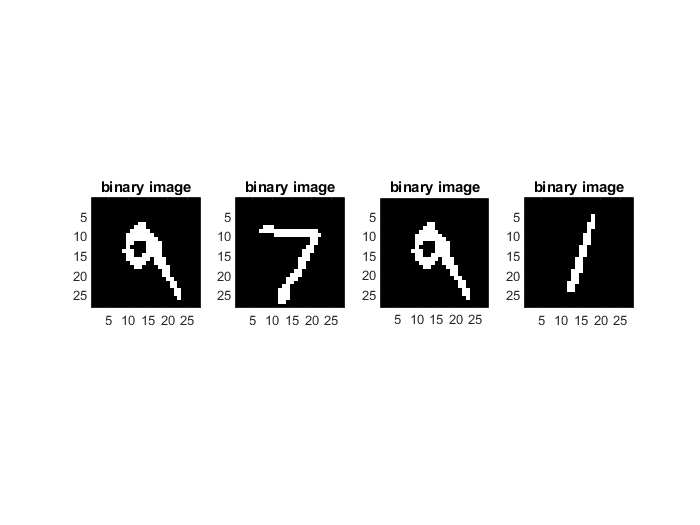

load('mnistb_test.mat')  % load binary MNIST digits
DB = mnistb_test;
[rows cols] = size(DB);
%
mymnist = uint8(zeros(4,785)); % array stores four images
% IDN = 9791
val = [9 7 9 1]; % array containing the digits of IDN
for num = 1:4
    for numseek = 1:rows % finds the digits of IDN in the MNIST database
        if DB(numseek,1) == val(num)
            mymnist(num,:) = DB(numseek,:);
            break % terminate search loop
        end
    end
    subplot(1,4,num)
    digIm = reshape(mymnist(num,2:785),[28,28]); % form the original 28x28 image
    digIm = digIm'; colormap(gray); imagesc(digIm); axis image; title('binary image')
end

- **Explanation: **DB is just a 2D array used to store the data from mnistb_test. mymnist is a 4 x 785 2D array that has been initialized with all 0's. The 0's act as dummy values until they are replaced. val is an array that contains the four digits of IDN; these four digits are the mnist images that MATLAB will look for as it goes through the mnist database. num is a dummy index variable that is used to iterate through the val array, which is why num runs from 1 to 4. numseek is another dummy index variable, and it's used to iterate through the rows of DB. The if statement is inside the nested for loop, which means that for every digit of IDN, MATLAB will search through all of the rows of DB to look for a row that matches that digit. Once a match is found, all the data in that row of DB are stored in a row of the mymnist array.

## Form DT of transmitted images.

DB = mymnist;  % from the previous section
[nImages,cols] = size(DB);
nFeatures = cols-1;
DT = zeros(1, 4*nFeatures); % preallocated array for transmitted bits
pDT = 1; % pointer to DT array
for row = 1:nImages
    x = DB(row,2:nFeatures+1);
    for column = 1:nFeatures
        bit = x(column);
        DT(pDT) = bit;
        pDT = pDT+1;
    end
end

#### Form DR errors with $PE=PE_{max}$ and display received images.

PE = PE_max

PE = 0.0850

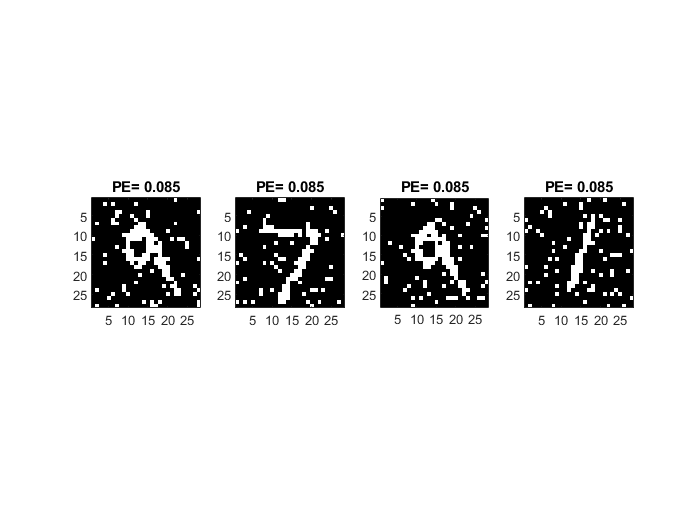

DR = DT; % make copy
for n = 1:length(DR)
    if rand() < PE
        DR(n) = xor(1,DR(n));
    end
end
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

- **Explanation: **The DR bit sequence contains all the pixel bits for the four images in order. Line 48 extracts the appropriate bits for each image and rearranges them into a 28 x 28 matrix. For each image number n, line 48 will take the nth set of 784 bits; for example, for n = 2 (second image), line 48 will take the second set of 748 bits (785:1496) and rearrange them into a 28 x 28 matrix. Once the pixel bits have been arranged into the 28 x 28 matrices, they are converted to 8-bit unsigned integers, then plotted in a single row of four images using lines 50 and 51.

#### DR2: What happens if the PE is doubled?

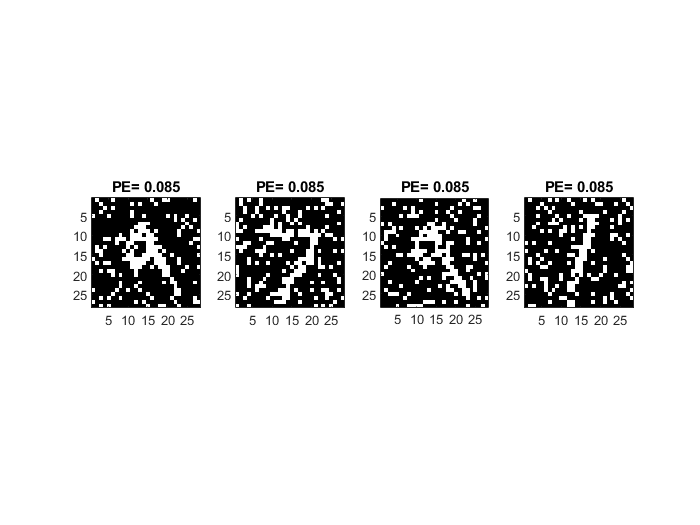

% DR2 code
DR2 = DT; % make copy
for n = 1:length(DR2)
    if rand() < 2*PE
        DR2(n) = xor(1,DR2(n));
    end
end
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR2(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

#### DR3: What happens if the PE is halved?

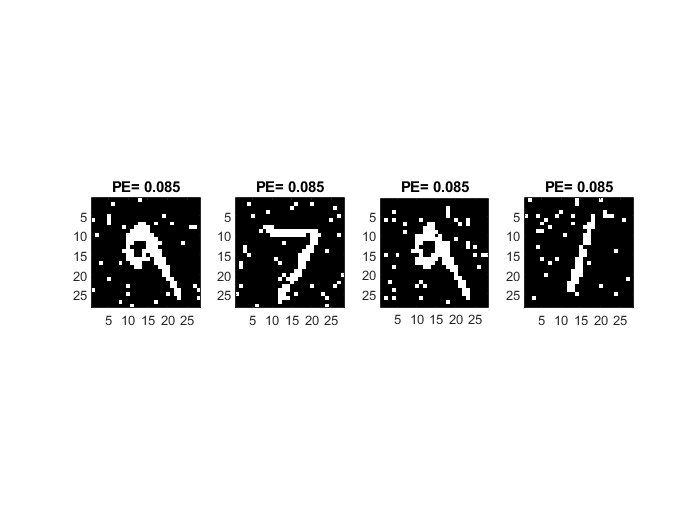

% DR3 code
DR3 = DT; % make copy
for n = 1:length(DR3)
    if rand() < 0.5*PE
        DR3(n) = xor(1,DR3(n));
    end
end
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR3(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

## Simulating a communication system

#### Designing a prototype signal:

Let's say we start with an arbitrary signal length of $N_{sig}= 40$.

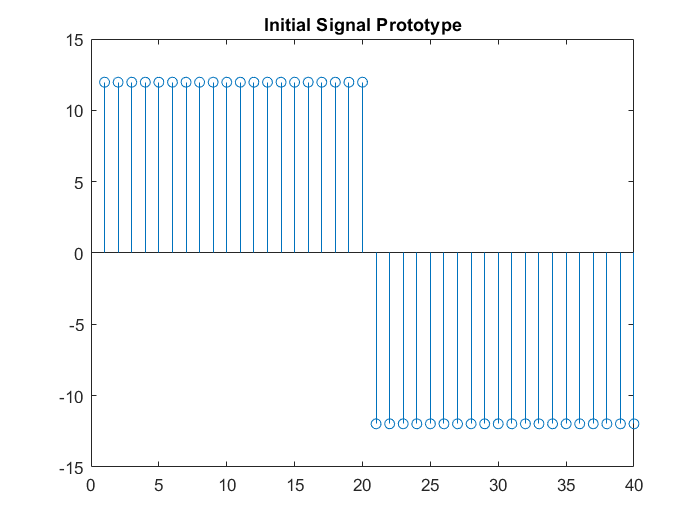

% trial prototype signal s
clf

Nsig = 40; 

Ndiv2 = Nsig/2;
s = [Amax*ones(1,Ndiv2) -Amax*ones(1,Ndiv2)];

stem(s)
title('Initial Signal Prototype')

- **Explanation: **I chose a binary signal type because it maximizes the signal energy for a given Nsig. For example, a sinusoidal signal type with the same Nsig would have half the energy.

#### Determining the minimum SNR that produces $PE \leq PE_{max{$. 

The following code estimates the $PE$ value by varying the $E_s/\sigma^2_N$ value and simulating DT bit transmissions by adding noise with variance $\sigma^2_N$.

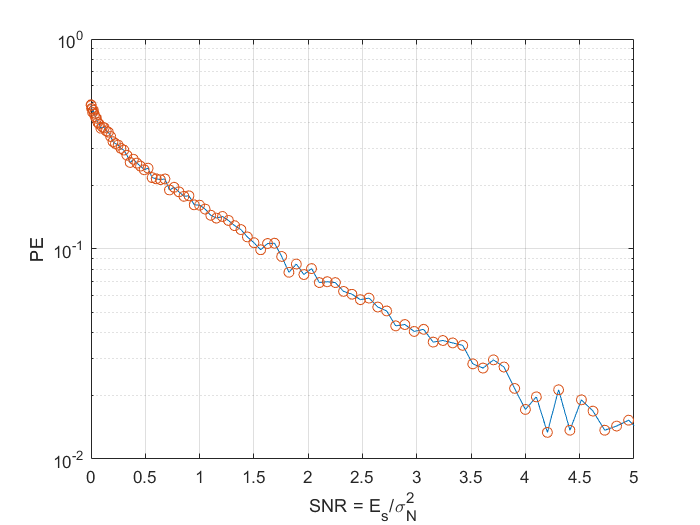

T = s;
Es = round(sum(s.^2));
Nval = 100; PE = zeros(1,Nval); SNR = zeros(1,Nval);
Nbits = length(DT);
for n = 1:Nval
    sigN = sqrt(Es)/(n/40); % a convenient set of values
    SNR(n) = Es/sigN^2;
    Nerr = 0; % initialize count to 0
    for i = 1:Nbits
        sT = s;
        if DT(i) == 0
            sT = -s;
        end
        G = randn(size(sT));
        SR = sT + sigN * G;
        V = sum(T.*SR);
        if V < 0
            DR = 0;
        else
            DR = 1;
        end
        if DR ~= DT(i)
            Nerr = Nerr +1;
        end
    end
    PE(n) = Nerr/Nbits;
end
semilogy(SNR,PE)
hold on
semilogy(SNR,PE,'o');grid on;xlabel('SNR = E_s/\sigma^2_N');ylabel('PE');xlim([0 5]);hold off;

PE_max

PE_max = 0.0850

- **From the graph, the signal energy **$E_{s,min}$** that achieves my **$PE_{max}$ is $E_{s,min} = SNR \cdot \sigma_N^2 = 1.9\ \cdot \ 6370.7 \approx\ 12104.33$

#### Computing $N_{sig}$ for the transmission signal so that it is an even number. 

The goal here is to find the minimum signal length such that the probability of error for bit transmission is below the $PE_{max}$ established in the design constraints. 

- **Computing the value of **$N_{sig}$** for my prototype signal from **$E_{s,min}$ 

- **Verifying the prototype gives **$E_s>E_{s,min}$**. **

- **Verifying **$E_{s,min}$** and SNR.**

- **Stem plotting the protoype signal sT = s.**

- **Stem plotting a typical signal in  noise  SR = sT+N.**

% code for calculations and display 
% 1.
E_smin = 12104.33;
N_sig = E_smin/Amax^2;
N_sigRound = ceil(N_sig)+1

N_sigRound = 86

% 2.
E_snew = N_sigRound * Amax^2

E_snew = 1.2327e+04

% 3. 
E_smin2 = (N_sigRound-2) * Amax^2 % E_smin2 is less than E_smin when N_sigRound-2 is less than N_sig

E_smin2 = 1.2041e+04

SNR2 = E_smin2/var_N

SNR2 = 1.8900

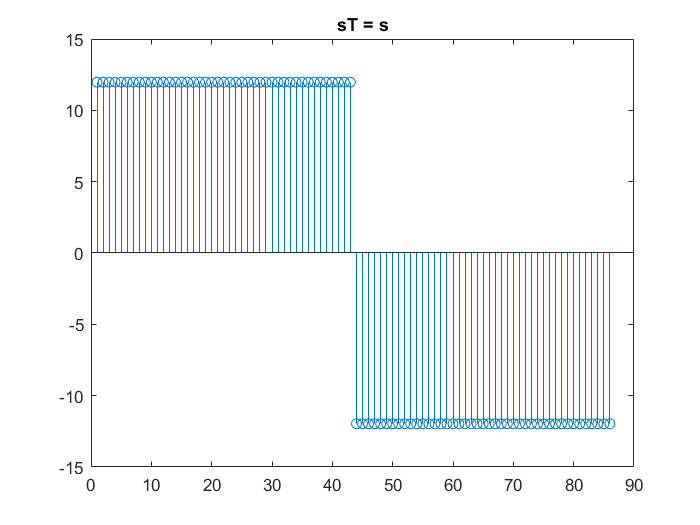

% 4.
Nsig = 86; 

Ndiv2 = Nsig/2;
sT = [Amax*ones(1,Ndiv2) -Amax*ones(1,Ndiv2)];
% I adjusted sT to have the length determined in question 1 of this
% section, which was Nsig = 86. Otherwise, it's the same as prototype
% signal s.

stem(sT)
title("sT = s")

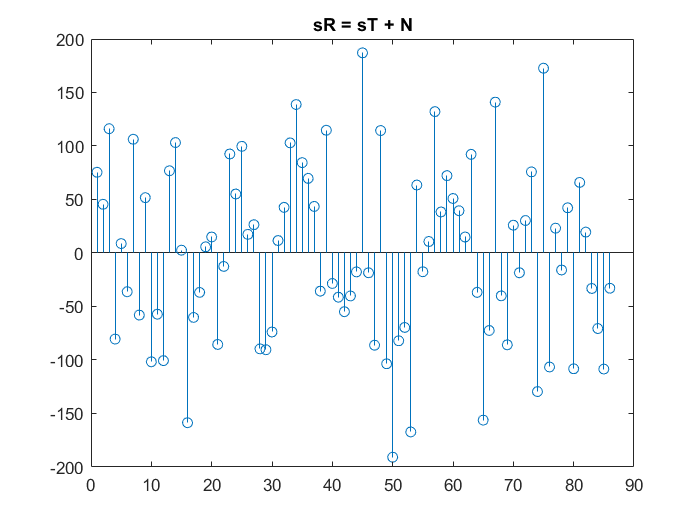

% 5.
N = sigma_N*randn(size(sT));
sR = sT + N;

stem(sR)
title("sR = sT + N")

### Communication system simulation with final prototype signal $s$.  

- **Modifying the communication system simulation above to use the prototype signal and to produce the **$PE_{sim}$** value.**

- **Verifying that **$PE_{sim} \leq PE_{max}$**.**

- **Computing the total energy to transmit the four images **$E_{sig,tot}$**.**

% displaying the current values of the important parameters to make sure they have not been changed by previous code
sigma_N

sigma_N = 79.8165

SNR= E_smin/sigma_N^2

SNR = 1.9000

% 1.
T = sT;

Nbits = length(DT);
    SNR = E_snew/sigma_N^2; % this is the SNR with the new signal energy that I calculated
                            % in part 2 of the section above
    Nerr = 0; % initialize count to 0
    for i = 1:Nbits
        ST = sT; 
        if DT(i) == 0
            ST = -sT;
        end
        G = randn(size(ST));
        SR = ST + sigma_N * G;
        V = sum(T.*SR);
        if V < 0
            DR = 0;
        else
            DR = 1;
        end
        if DR ~= DT(i)
            Nerr = Nerr +1;
        end
    end
    
    % PE_sim value is indeed less than PE_max (0.0850)
    PE = Nerr/Nbits

PE = 0.0851

% 3.
% E_sig,tot is the signal energy for transmitting one bit (E_snew) times
% the number of bits that need to be transmitted (Nbits)
E_sigtot = E_snew*Nbits

E_sigtot = 3.8658e+07

## Error correction with bit repetition

- **Composing a communication system simulation program that incorporates error correction.**

- **Computing error probability using error correction **$PE_{EC}$**.**

- **Compute the total energy to transmit the four images using error correction **$E_{EC,tot}$**.**

% 1.
% EC program
sigma_N

sigma_N = 79.8165

SNR= E_smin/sigma_N^2

SNR = 1.9000

NumRep = 6;  % Number of repetitions for each data bit (number of bits per codeword)


PE = 0.0851

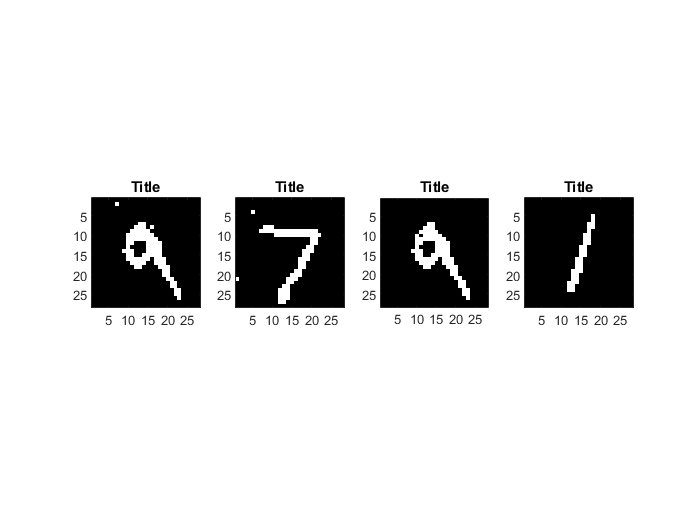

title(['Image with noise PE= ' num2str(PE)])

NumRep; % number of repeated bits transmitted
ECBdigit = DT;  % ECBdigit will start with no errors
DR_EC = []; % empty received bit array
if NumRep > 0
    for j = 1:length(DT)  % examine each bit in DT
        ECbits = []; % start with empty EC vector
        for Rep = 1:NumRep
            bitval = DT(j); % original bit value
            ST = sT; % I changed the dummy signal variable sT to ST since I already named my
             % transmitted signal sT in the previous section
            if DT(j) == 0
                ST = -sT;
            end
            G = randn(size(ST)); % here, I generate some Gaussian noise for each bit
            SR = ST + sigma_N * G;
            V = sum(T.*SR);
            if V < 0
                bitval = 0;
            else
                bitval = 1;
            end
            ECbits = [ECbits bitval]; % append bit to EC code word
        end
        ECmode = mode(ECbits); % find bit with most votes in each codeword
        DR_EC(j) = ECmode; % now, DT has had noise added and the codewords have been "interpreted,"
                              % which yields our updated ECBdigit.
    end
end
    
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR_EC(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im')
    colormap('gray');axis image;drawnow
    title(["Title"])
end

% 2.
% To find PE_EC, I just compared each bit of DR_EC to each bit of DT.
Nbits = length(DR_EC);
    Nerr = 0; % initialize count to 0
    for i = 1:Nbits
        if DT(i) ~= DR_EC(i)
            Nerr = Nerr +1;
        end
    end
    
    % PE_EC is the probability of error when there are 6 repeated bits
    PE_EC = Nerr/Nbits

PE_EC = 0.0016

% 3.

% E_EC,tot is just the signal energy of one bit (E_snew) times the number
% of bits.
E_ECtot = E_snew*Nbits*NumRep

E_ECtot = 2.3195e+08

## Analyzing the final communication system design.

- **Trade-offs in the final design. **Amount of data transmitted (and therefore time needed to transmit) and energy required to transmit were increased, but the probability of error was reduced drastically.

- **Ideal changes system specification that could be made to improve the system performance: **If one change could be made, the electrical power (battery voltage) would be increased. Increasing the power would increase Amax, thus increasing signal energy. Increasing the signal energy would either raise the SNR or allow for data to be transmitted faster while maintaining the smae SNR that I have now. In order to increase electrical power, a higher voltage battery or power source would be needed. I would also need to ensure that the circuits of the transmission equipment can handle the higher voltage.